# 16-QAM with MATLAB Functions

## Introduction

This section builds an example step-by-step to give you a first look at the Communications System Toolbox™ software. This section also shows how Communications System Toolbox functionalities build upon the computational and visualization tools in the underlying MATLAB® environment.

## Modulating a Random Signal

This example shows how to process a binary data stream using a communication system that consists of a baseband modulator, channel, and demodulator. The system's bit error rate (BER) is computed and the transmitted and received noisy signals are displayed in a constellation diagram.

The following table summarizes the basic operations used, along with relevant Communications System Toolbox and MATLAB functions. The example uses baseband 16-QAM (quadrature amplitude modulation) as the modulation scheme and AWGN (additive white Gaussian noise) as the channel model.

The following functions from the Toolbox are used

Task / Function

Generate a Random Binary Data Stream / randi

Convert the Binary Signal to an Integer-Valued Signal / bi2de

Modulate using 16-QAM / qammod

Add White Gaussian Noise / awgn

Create a Constellation Diagram / scatterplot

Demodulate using 16-QAM / qamdemod

Convert the Integer-Valued Signal to a Binary Signal / de2bi

Compute the System BER / biterr

## Generate a Random Binary Data Stream

The conventional format for representing a digital signal in MATLAB is a vector or a matrix. This example uses the 'randi' function to create a column vector that contains (n) values of a binary data stream. The length of the binary data stream (that is, the number of rows in the column vector) is arbitrarily set to n=10,000 = 1e4.

The code below also shows first few bits from this data vector in a stem plot. Notice the use of the colon (:) operator in MATLAB to select the elements with indices (start:stop) of the data.

Define parameters.

clear all; close all; clc;

M = 16;                     % Size of signal constellation
k = log2(M);                % Number of bits per symbol
n = 10000;                  % Number of bits to process
numSamplesPerSymbol = 1;    % Oversampling factor

Note:   The numSamplesPerSymbol variable is not significant in this example but will make it easier to extend the example later to use pulse shaping.

Create a binary data stream as a column vector.

Use the randi function to generate random binary data. The rng function should be set to its default state so that the example produces repeatable results.

rng default                 % Use default random number generator
dataIn = randi([0 1],n,1);  % Generate column n-vector of binary data

Plot the first 20 bits in a stem plot.

display(dataIn(1:20)')

  Columns 1 through 12

     1     1     0     1     1     0     0     1     1     1     0     1

  Columns 13 through 20

     1     0     1     0     0     1     1     1



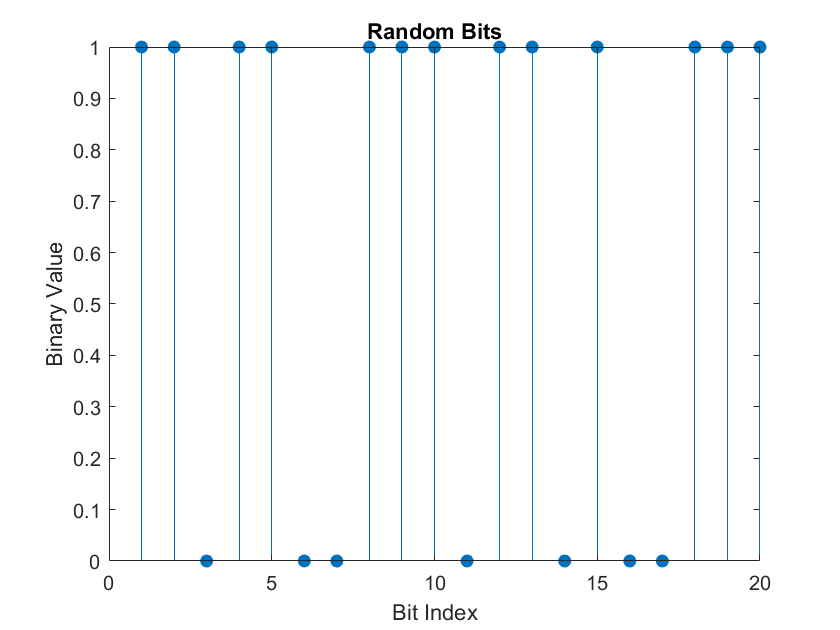

figure();
stem(dataIn(1:20),'filled');
title('Random Bits');
xlabel('Bit Index');
ylabel('Binary Value');

## Convert the Binary Signal to an Integer-Valued Signal

The qammod function implements a rectangular, M-ary QAM modulator, M=16 in this example.

**By default, 'qammod' object receives integers between 0 and 15 rather than 4-tuples of bits.**

Thus, it is necessary to transform the binary data stream dataIn before using the 'qammod' function. In particular, the 'bi2de' function is used to convert each block of 4 bits into a corresponding integer. 

Perform a bit-to-symbol mapping.

% Reshape data into binary k-tuples, k = log2(M). Can also use 'reshape'
dataInMatrix = reshape(dataIn,length(dataIn)/k,k);
% Convert to integers
dataSymbolsIn = bi2de(dataInMatrix);

Plot the decimal index of the first 10 symbols in a stem plot.

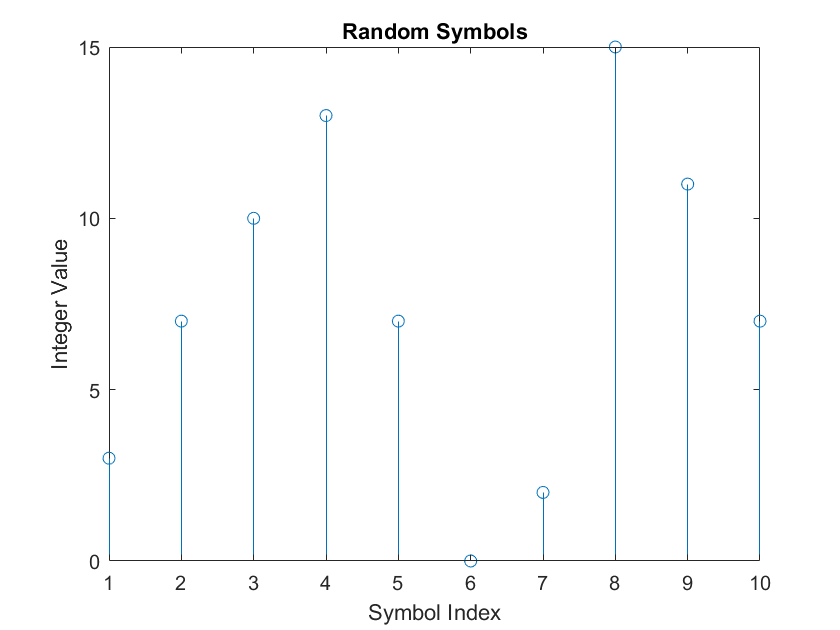

figure; % Create new figure window.
stem(dataSymbolsIn(1:10));
title('Random Symbols');
xlabel('Symbol Index');
ylabel('Integer Value');

## Modulate using 16-QAM

Having generated the dataSymbolsIn column vector, use the 'qammod' function to apply 16-QAM modulation for both binary and Gray coded bit-to-symbol mappings. Gray coding is the default in 'qammod' and will be later omitted in input arguments.

Recall that M=16, the modulation alphabet size.

Apply modulation.

% Binary coding
dataMod = qammod(dataSymbolsIn,M,'bin');
% Gray coding is the default
dataModG = qammod(dataSymbolsIn,M,'gray');

The results are vectors of complex numbers, each representing a symbol of 16-QAM signal constellation. The real and imaginary parts of each symbol correspond to the components modulating the amplitude of the In-phase "I", the cos() carrier and the Quadrature "Q", the sin() carrier.

A later step in this example will plot the constellation diagram.

To learn more about modulation functions, see Digital Modulation. 

**Note : The 'qammod' function does not apply pulse shaping.**

To extend this example to use pulse shaping, see Pulse Shaping Using a Raised Cosine Filter. For an example that uses Gray coding with PSK modulation, see Gray Coded 8-PSK.

## Add White Gaussian Noise

The ratio of bit energy to noise power spectral density, Eb/N0, is arbitrarily set to 10 dB. From that value, the per-symbol signal-to-noise ratio (SNR) can be determined. Given the SNR, the modulated signal, dataMod, is passed through the channel by using the 'awgn' function.

Note:   The numSamplesPerSymbol variable is not significant in this example but will make it easier to extend the example later to use pulse shaping.

Calculate the SNR when the channel has an Eb/N0 = 10 dB.

EbNo = 10;
snr = EbNo + 10*log10(k) - 10*log10(numSamplesPerSymbol);

Pass the signal through the AWGN channel for both the binary and Gray coded symbol mappings.

receivedSignal = awgn(dataMod,snr,'measured');
receivedSignalG = awgn(dataModG,snr,'measured');

## Create a Constellation Diagram

The 'scatterplot' function (Comm Systems Toolbox) is used to display the in-phase and quadrature components of the modulated signal, dataMod, and its received, noisy version, receivedSignal. By looking at the resulting diagram, the effect of the noise is observable - the received noisy versions of the transmitted symbols are scattered, misplaced, with respect to the reference symbols.

Use the scatterplot function to show the constellation diagram.

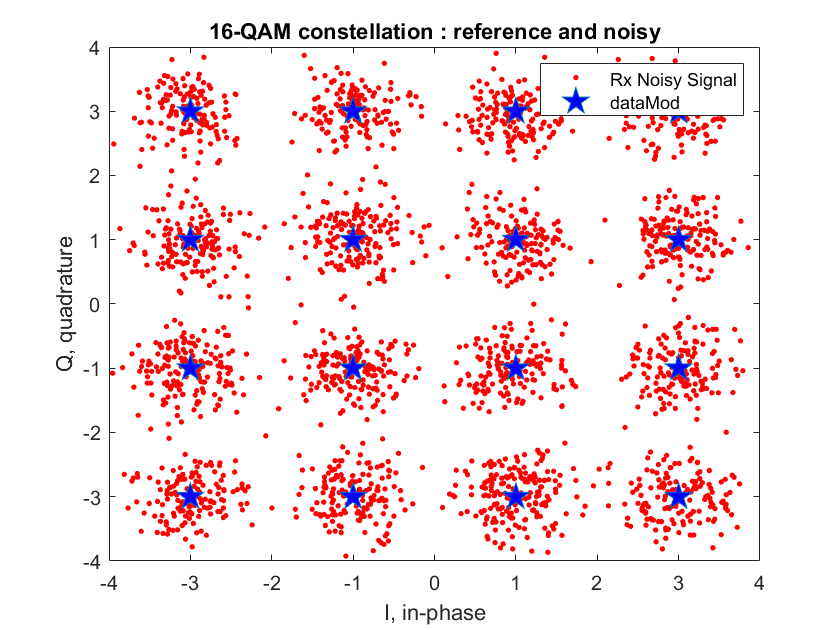

figure;
plot(real(receivedSignal),imag(receivedSignal),'r.','MarkerSize',8)
hold on
plot(real(dataMod),imag(dataMod),'p','MarkerFaceColor','blue','MarkerSize',14)
title('16-QAM constellation : reference and noisy')
legend(['Rx Noisy Signal'],'dataMod' )
xlabel('I, in-phase')
ylabel('Q, quadrature')
axis([-4 4 -4 4])

## Demodulate 16-QAM

The 'qamdemod' function is used to demodulate the received data and output integer-valued data symbols.

dataSymbolsOut = qamdemod(receivedSignal,M,'bin');
dataSymbolsOutG = qamdemod(receivedSignalG,M);

## Convert the Integer-Valued Signal to a Binary Signal

The de2bi function is used to convert the data symbols from the QAM demodulator, dataSymbolsOut, into a binary matrix, dataOutMatrix with dimensions of [Nsym x N bits/sym], where Nsym is the total number of QAM symbols and Nbits/sym=k=4 is the number of bits per symbol. The matrix is then converted into a column vector whose length is equal to the number of input bits 10,000. The process is repeated for the Gray coded data symbols, dataSymbolsOutG.

Reverse the bit-to-symbol mapping performed earlier.

dataOutMatrix = de2bi(dataSymbolsOut,k);
dataOut = dataOutMatrix(:);                   % Return data in column vector
dataOutMatrixG = de2bi(dataSymbolsOutG,k);
dataOutG = dataOutMatrixG(:);                 % Return data in column vector

## Compute the System BER (Bit Error Rate)

The function 'biterr' is used to calculate the bit error statistics from the original binary data stream, dataIn, and the received data streams, dataOut and dataOutG.

Use the error rate function to compute the error statistics and use 'fprintf' to display the results.

[numErrors,ber] = biterr(dataIn,dataOut);
[numErrorsG,berG] = biterr(dataIn,dataOutG);
fprintf('\nThe binary coding bit error rate = %5.2e, based on %d errors\n', ...
    ber,numErrors)


The binary coding bit error rate = 2.10e-03, based on 21 errors


fprintf('\nThe Gray coding bit error rate = %5.2e, based on %d errors\n', ...
    berG,numErrorsG)


The Gray coding bit error rate = 1.10e-03, based on 11 errors


Observe that Gray coding significantly reduces the bit error rate.

# Plot Signal Constellations

The example in the previous section, Modulating a Random Signal, created a scatter plot from the modulated signal. Although this plot showed the points in the QAM constellation, it did not indicate which integers of the modulator are mapped to a given constellation point. This section illustrates two possible mappings: 1) binary coding, and 2) Gray coding (default in 'qammod'). It was previously demonstrated that Gray coding provides smaller bit error rate, and thus is preferred.

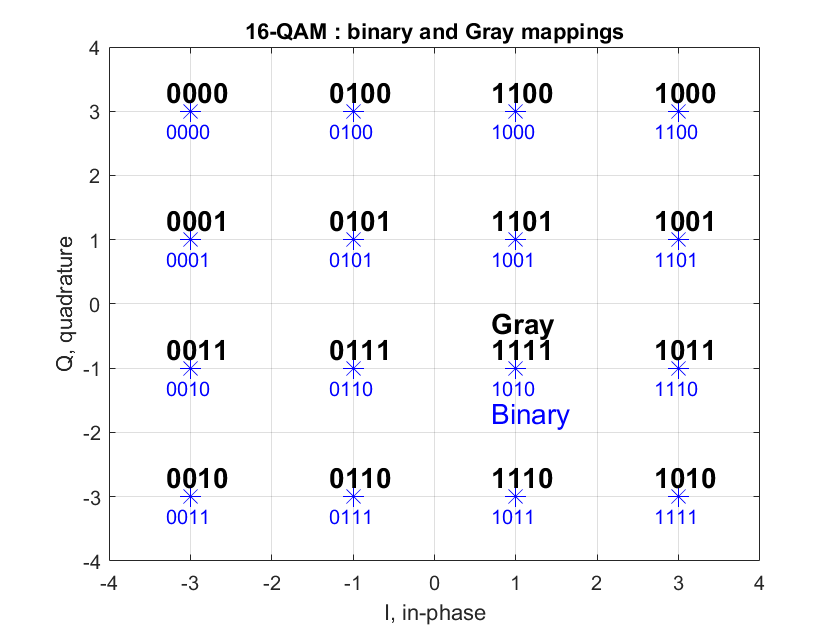

x = (0:15)';

% Convert the input vector from a natural binary order to a Gray encoded
% vector using 'bin2gray'.
y = bin2gray(x,'qam',16);
% 16-QAM constellation to be used with different symbol mappings
% 16-QAM output, Gray-coded by default.
symbols = qammod(x, 16);
% Plot the constellation symbols and label them using the 
% Gray, 'y' and binary, 'x', output vectors.
figure;
plot(real(symbols),imag(symbols),'b*','MarkerSize',10)
hold on
grid on
title('16-QAM : binary and Gray mappings')
xlabel('I, in-phase')
ylabel('Q, quadrature')
axis([-4 4 -4 4])

for k = 1:16
    text(real(symbols(k))-0.3,imag(symbols(k))+0.3,...
        dec2base(x(k),2,4),'FontSize',14,'FontWeight','bold');
    text(real(symbols(k))-0.3,imag(symbols(k))-0.3,...
        dec2base(y(k),2,4),'Color',[0 0 1]);
end

text(real(symbols(k))-0.3,imag(symbols(k))+0.7,...
    'Gray','FontSize',14,'FontWeight','bold');
text(real(symbols(k))-0.3,imag(symbols(k))-0.7,...
    'Binary','FontSize',14,'Color',[0 0 1]);

## Examine the Plots

- In the binary mapping plot, notice that natural order symbols 1 (0 0 0 1) and 2 (0 0 1 0) correspond to adjacent constellation points on the left side of the diagram. The binary representations of these integers differ by two bits ...

- ... unlike the Gray-coded signal constellation in which each constellation symbol points that are adjacent, and thus, the most vulnerable to the noise and contributing the most to the residual errors after the demodulation, differ by only one bit from their direct neighbors, thus leading to better BER performance.

# Comparison of M-QAM modulations over AWGN channel

In this section, we integrate the previous code into the loop over EbN0, and compare the BER for 4-QAM, 16-QAM, 64-QAM and 256-QAM. The Gray coding is used.

The ratio of bit energy to noise power spectral density, Eb/N0, is arbitrarily set in the range of [0:10] dB. From that value, the signal-to-noise ratio (SNR) can be determined. Given the SNR, the modulated signal, dataMod, is passed through the channel by using the 'awgn' function.

In order to have the 95% confidence in BER estimate, we need to process approximately n = K/BER bits, where K=100. We set n = 1e7, so as to get to BER ~= 1e-5 .

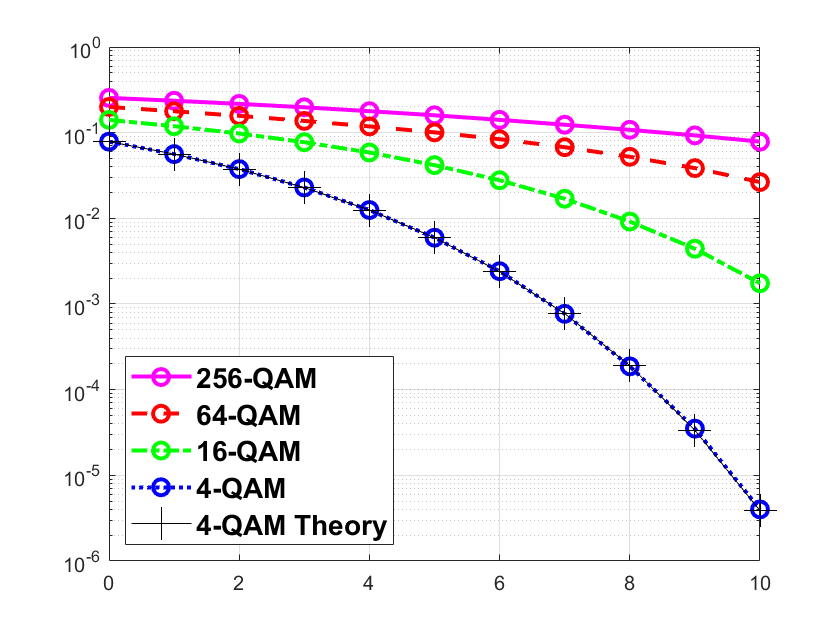

clear all; close all; clc;

M = [4 16 64 256];          % Size of signal constellation
k = log2(M);                % Number of bits per symbol
n = 1e7;                    % Number of bits to process

rng default    % Use default rng - random number generator
dataIn = randi([0 1],n,1);  % Generate vector of binary data
EbNodB = [0 : 10];          % Eb/N0 range in dB
berG   = [];                % BER results, Gray

for im = 1 : length(M)
    
    % Reshape data into binary k-tuples, k = log2(M)
    % Use vec2mat to manage the zero-padded bits
    [dataInMatrix Nbjammod] = vec2mat(dataIn,k(im));
    % Convert to integers
    dataSymbolsIn = bi2de(dataInMatrix,'left-msb');

    % Gray coding is used by default in 'qammod'
    dataModG = qammod(dataSymbolsIn,M(im));

    % Have to loop over EbNodB values, since 'awgn' only 
    % accepts scalar snr parameter
    for isnr = 1 : length(EbNodB)
        snr = EbNodB(isnr) + 10*log10(k(im));
        receivedSignalG = awgn(dataModG,snr,'measured');
        dataSymbolsOutG = qamdemod(receivedSignalG,M(im));
      
        % Some arrangements to transform back to binary and 
        % suppress the jamming bits
        tmp_mx = de2bi(dataSymbolsOutG,'left-msb');
        tmp_mx = tmp_mx.';  tmp_mx = tmp_mx(:);
        dataOutG = tmp_mx(1:end-Nbjammod);
        
        % Compute the BER
        [numErrorsG,berG(im,isnr)] = biterr(dataIn,dataOutG);
    end
end
        
% Plotting
figure;
semilogy(EbNodB, berG(4,:),'-om','LineWidth',2,'MarkerSize',8);
hold on; grid on;
semilogy(EbNodB, berG(3,:),'--or','LineWidth',2,'MarkerSize',8);
semilogy(EbNodB, berG(2,:),'-.og','LineWidth',2,'MarkerSize',8);
semilogy(EbNodB, berG(1,:),':ob','LineWidth',2,'MarkerSize',8);
semilogy(EbNodB, 1/2*erfc(sqrt(10.^(EbNodB/10))),'-k+','MarkerSize',16);

hleg1 = legend('256-QAM', '64-QAM', '16-QAM', '4-QAM', '4-QAM Theory');
hleg1.Location = 'southwest';
hleg1.FontSize = 14;
hleg1.FontWeight = 'bold';

Observe, that the higher is the constellation size M, the more vulnerable is the modulation to the noise, that is **for given Eb/N0, the modulation with bigger M has higher error probability**, since the distance between the adjacent symbols is smaller (the same constellation energy is supposed). On the counterpart, for a given fixed symbol rate, the bigger number of bits is mapped onto each symbol (2 bit/symbol for 4-QAM and 8 bits/symbol for 256-QAM), and thus, the higher the bitrate is.

To validate, the 4-QAM theoretical BER is plotted, given by the analytical formula : $P_b = Q\left(\sqrt{\frac{2 E_b}{N_0}}\right) = \frac{1}{2} \cdot \mathrm{erfc} \left( \sqrt{\frac{E_b}{N_0}} \right)$.